# TP4 : 

- VIN Charles

- RECHAK LAMBERT Dorian

METTRES DES TITRES AUX GRAPHIQUES

## Exercice 1 :

Instanciation des constantes :

w_p = 0.2*pi;
w_s = 0.3*pi;
R_p = 7; % db? 
A_s = 16;

### Question 1 :

Calcul de N

N = floor(log10( ...
        ((10^(R_p/10) - 1 )*(10^(A_s/10) - 1))...
        / ...
        (2*log10(w_p/w_s)) ...
       )) + 1;
N = real(N);
N

Calcul de $w_c$

w_cp = w_p / (10^(R_p/10) - 1)^(1/(2*N));
w_cs = w_s / (10^(A_s/10) - 1)^(1/(2*N));
w_c = (w_cp + w_cs)/2;
w_c

### Question 2 :

On a donc $N=3$, donc 3*2=6 pôles. Dont 3 instables. Les pôles stables ont pour argument : 2pi/3, pi, 4pi/3

%Calcul des pôles
p_1 = w_c * exp(1i*2*pi/3);
p_2 = w_c * exp(1i*pi);
p_3 = w_c * exp(1i*4*pi/3);
p_1, p_2, p_3

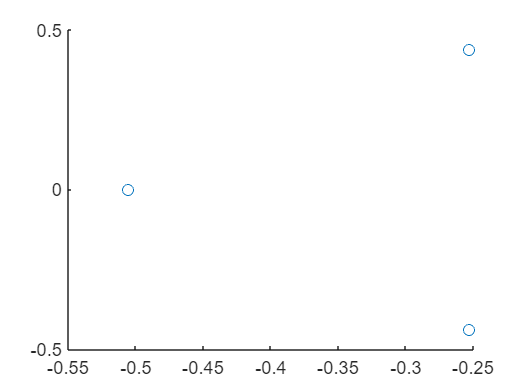

% Plot des pôles
x = real([p_1 p_2 p_3]);
y = imag([p_1 p_2 p_3]);
scatter(x,y);

### Question 3, 4:

f = 0 : 0.01 : 3;
w = 2*pi*f;
S = 1i*w;
H = w_c.^N ./ ((S - p_1).*(S - p_2).*(S - p_3));

H =    1.0000 + 0.0000i   0.9691 - 0.2468i   0.8761 - 0.4819i   0.7198 - 0.6923i   0.4977 - 0.8587i   0.2146 - 0.9483i  -0.0965 - 0.9185i  -0.3590 - 0.7537i  -0.4972 - 0.5106i  -0.5076 - 0.2823i  -0.4456 - 0.1202i  -0.3633 - 0.0234i  -0.2869 + 0.0281i  -0.2243 + 0.0526i  -0.1756 + 0.0622i  -0.1382 + 0.0640i  -0.1098 + 0.0618i  -0.0880 + 0.0578i  -0.0712 + 0.0532i  -0.0581 + 0.0484i  -0.0479 + 0.0438i  -0.0397 + 0.0396i  -0.0333 + 0.0357i  -0.0280 + 0.0322i  -0.0238 + 0.0291i  -0.0203 + 0.0264i  -0.0174 + 0.0239i  -0.0150 + 0.0217i  -0.0130 + 0.0198i  -0.0114 + 0.0180i  -0.0100 + 0.0165i  -0.0088 + 0.0151i  -0.0077 + 0.0139i  -0.0068 + 0.0128i  -0.0061 + 0.0118i  -0.0054 + 0.0109i  -0.0049 + 0.0100i  -0.0044 + 0.0093i  -0.0039 + 0.0086i  -0.0035 + 0.0080i  -0.0032 + 0.0075i  -0.0029 + 0.0070i  -0.0026 + 0.0065i  -0.0024 + 0.0061i  -0.0022 + 0.0057i  -0.0020 + 0.0053i  -0.0018 + 0.0050i  -0.0017 + 0.0047i  -0.0016 + 0.0044i  -0.0014 + 0.0042i


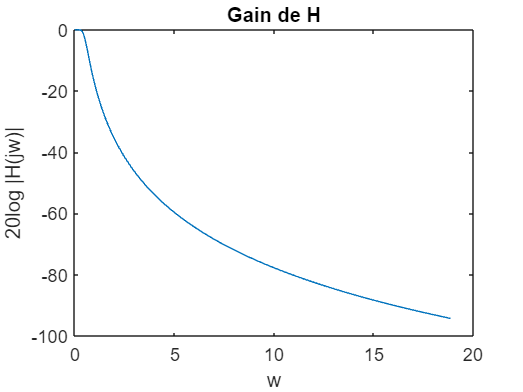

%Plot 
module = 20*log10(abs(H));
phase = unwrap(angle(H));
% IL FAUT VERIFIER ENTER 0.2pi et 0.3pi si on descend bien de r_p a_s
figure('name', 'Gain de H');
plot(w, module);
title('Gain de H');
xlabel('w');
ylabel('20log |H(jw)|');

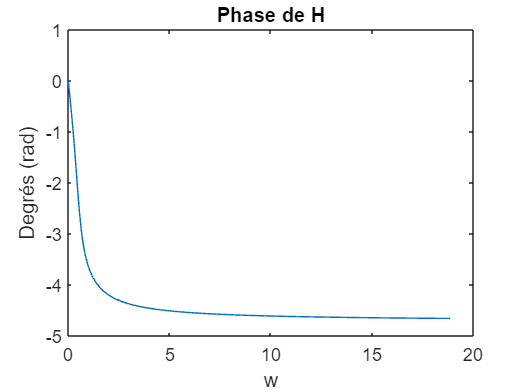


figure('name', 'Phase de H');
plot(w, phase);
title('Phase de H');
xlabel('w');
ylabel('Degrés (rad)');

## Exercice 2 :

Conversion des paramètres

T = 1

T = 1

W_p = 0.2 * pi;
W_s = 0.3 * pi;

w_p = (2/T) * tan(W_p/2); % Conversion des paramètres
w_s = (2/T) * tan(W_s/2); % Conversion des paramètres
R_p = 7;
A_s = 16;

### Question 1 : 

N = floor(log10( ...
        ((10^(R_p/10) - 1 )*(10^(A_s/10) - 1))...
        / ...
        (2*log10(w_p/w_s)) ...
       )) + 1;
N = real(N);
N

On a également N=3, donc 3*2=6 pôles. Dont 3 instables. Les pôles stables ont encore une fois pour argument : 2pi/3, pi, 4pi/3

w_cp = w_p / (10^(R_p/10) - 1)^(1/(2*N));
w_cs = w_s / (10^(A_s/10) - 1)^(1/(2*N));
w_c = (w_cp + w_cs)/2;

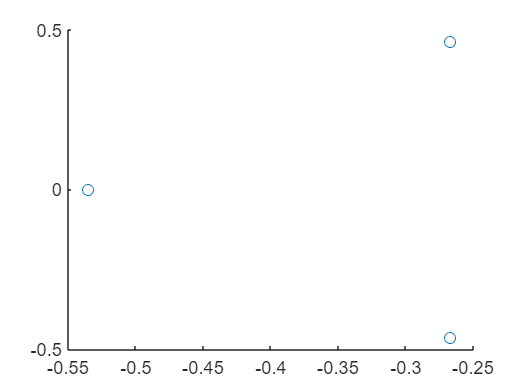

p_1 = w_c * exp(1i*2*pi/3);
p_2 = w_c * exp(1i*pi);
p_3 = w_c * exp(1i*4*pi/3);
x = real([p_1 p_2 p_3]);
y = imag([p_1 p_2 p_3]);
scatter(x,y);

p_1, p_2, p_3

p_1 = -0.2673 + 0.4630i

p_2 = -0.5347 + 0.0000i

p_3 = -0.2673 - 0.4630i

### Question 2 : 

Transformation bilinéaire

f = 0 : 0.01 : 3;
w = 2*pi*f;
Z = exp(1i*w);

S = (2/T) * (1-Z.^(-1))./(1 + Z.^(-1)); % Transformation bilinéaire
H = w_c.^N ./ ((S - p_1).*(S - p_2).*(S - p_3));

Plot du module et de la phase

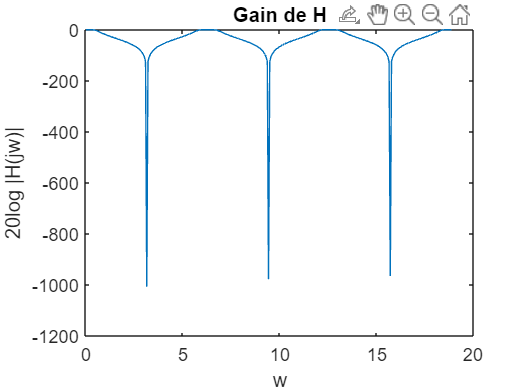

module = 20*log10(abs(H));
phase = unwrap(angle(H));

figure('name', 'Gain de H');
plot(w, module);
title('Gain de H');
xlabel('w');
ylabel('20log |H(jw)|');

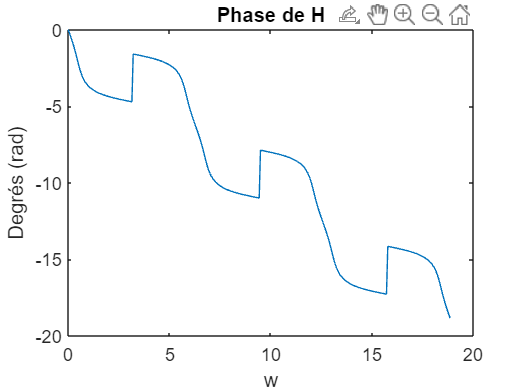


figure('name', 'Phase de H');
plot(w, phase);
title('Phase de H');
xlabel('w');
ylabel('Degrés (rad)');